# Make FEEM plots

edit the file data.m. That will include -99 as the top left corner (or any number arbitrary number, it is just there to avoid a "matrix size" error). The top row are the ex wavelengths. the left row is the em wavelengths. The "middle" is the fluorescence values. Change data.m for whatever data you are looking at.

% need the path the the data file and the processing files

filePath = matlab.desktop.editor.getActiveFilename;
for i = length(filePath):-1:1
    if filePath(i) == '/'
        slash(i,1) = 1;
    end
end
filePath = filePath(1:length(slash) );
cd (filePath);

%txt=pwd; n=length(txt);
%rootpath=txt(1:n-8);
%PHREEQCpath=[rootpath,'runPHREEQC'];
%addpath(PHREEQCpath);

% load the data. you have to restart kernel after every data change
run("originaldata.m")

# Now make the plots

you need to decide the width of the scatter line. default is 0.02 but sometimes a larger value is necessary to remove all the scatter (scatter depends on molecular size and is not the same for all samples (or spectrometers for that matter). You also need to set the minimum excitation wavelengths. Some instruments give a lot of data at excitation wavelengths with no fluorescence (Aqualog for example) and often low excitation wavelengths are just noise that make the rest of the scan hard to read (most instruments operate in ratio mode where the fluorescence is divided by the incident light intensity, low intensity excitation light at low wavelengths results in very large, but noisy signals).

You can change the settings and rerun the plots without restarting the kernel (select "Run" tab and then "Run all cells" or for a specific graph just click the "play" button on the top ribbon bar when that cell is selected).

There is an optional flag. If it is set to 1 then all zero values in the original data will be replaced by NaN (not a number). the reason for this is that sometimes an instrument will automatically set values where emission is less than excitation to zero (you can't have more energy out than you put in). With the way I do background subtraction this can lead to strange looking data, so replacing it with NaN potentially takes care of that.

%contour plot over colourmap.
scatterfactor=0.02; exmin=220; exmax=400; flag=1;
[F,em,ex]=Fprocess(data,scatterfactor,exmin,exmax,flag);
figure(1); makecontourplot(F,em,ex)

black and white contour plot

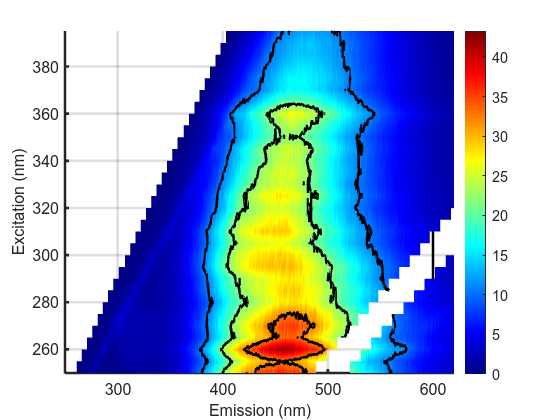

%black and white contour plot
% need to define the number of contour lines

num=3;
figure(2); makesimplecontourplot(F,em,ex,num)

3D mesh plot

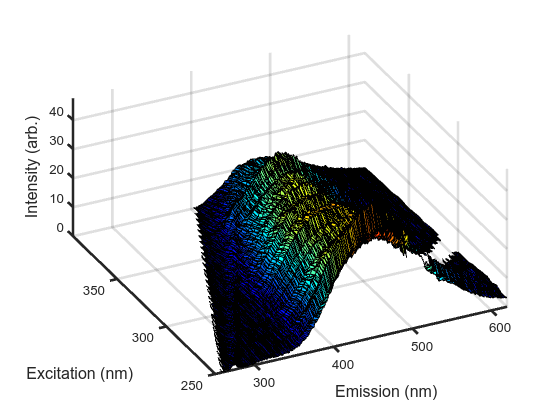

%plot of all the data in 3D
figure(3); makesurfaceplot(F,em,ex)

3D mesh resampled data

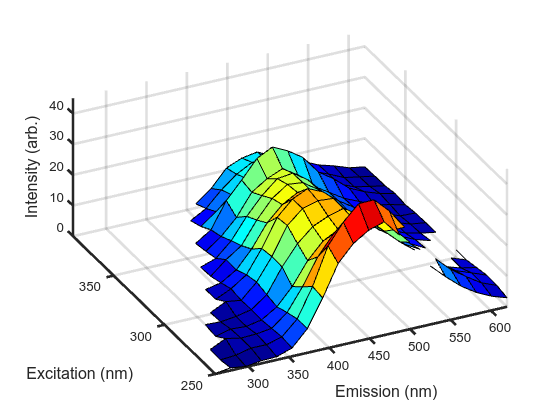

% resample the data to improve the appearance of the plot.  looks better if ex and
% em are sampled at similar resolution
% you need to set the samplefreq parameter
samplefreq=20; %divide ex and em into samplereq equal steps.  so bigger number closer.
[Fr,emr,exr]=resample(F,em,ex,samplefreq); %
figure(4); makesurfaceplot(Fr,emr,exr)

3D wire mesh

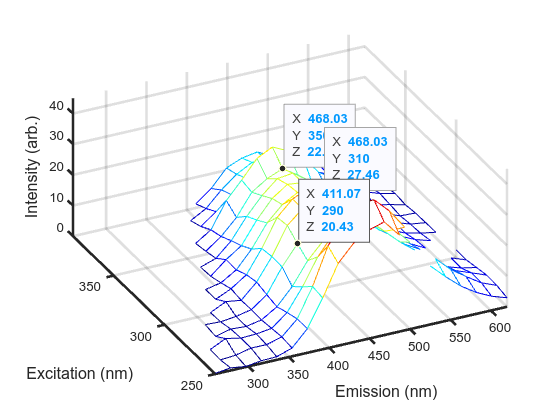

% resampled plot but with a wire mesh look
figure(5); makemeshplot(Fr,emr,exr)